# Análise de Vogais

Pedro Henrique Sant Anna Hein 20.00134-7

Ao dar "Run" é exibido todos os gráficos, a frequência fundamental (f0) e as formantes (f1 e f2) de cada vogal. Além disso, será reproduzido o som de cada vogal sintetizada e depois a sequência AUA.

A função "get_sintese" é executada em um arquivo separado (.m) e invoca todas as variáveis necessárias para a sintese da vogal

## Boas Práticas

clear all;      % Limpa as variáveis
close all;      % fecha as figuras
clc;            % limpa a tela

## Sintese das vogais

%Vogal A
[VG_a, fs_a] = audioread("a1.wav");
disp("VOGAL A")

VOGAL A


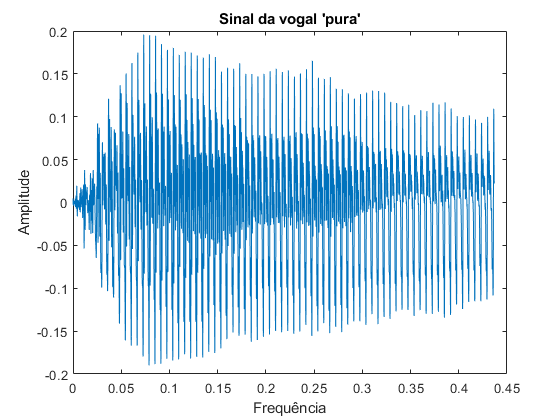

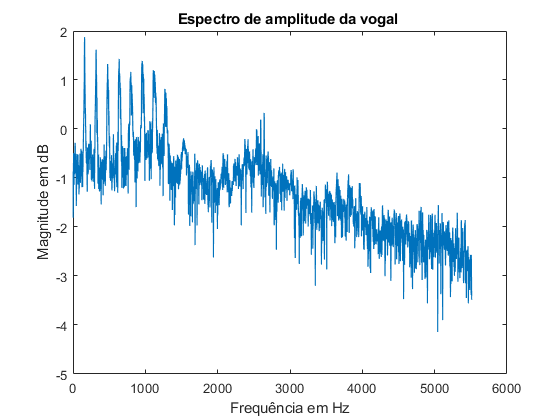

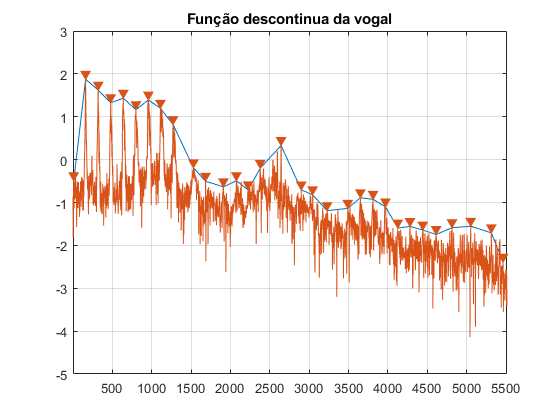

f0 = 161.4252

f1 = 639.9766

f2 = 958.2477

fx =      General model Exp1:
     fx(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1809  (0.09336, 0.2685)
       b =      -454.2  (-818.9, -89.5)

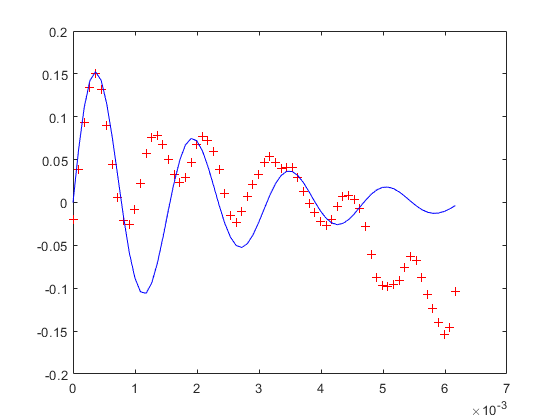

Gs =
 
           727.42
  -------------------------
  (s^2 + 908.4s + 1.637e07)
 
Continuous-time zero/pole/gain model.



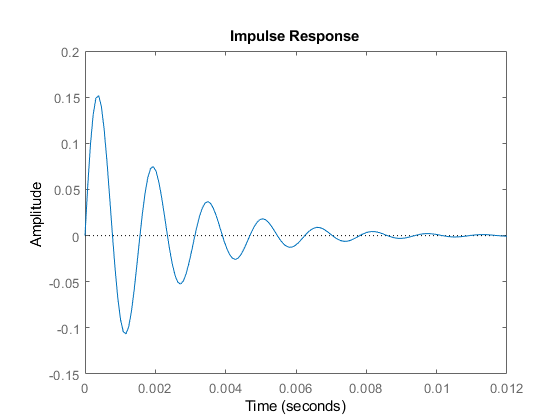

impulso_a = get_sintese(VG_a, fs_a, 639.9);

sound(impulso_a,fs_a*2)
pause(1)

%Vogal E
[VG_e, fs_e] = audioread("e1.wav");
disp("VOGAL E")

VOGAL E


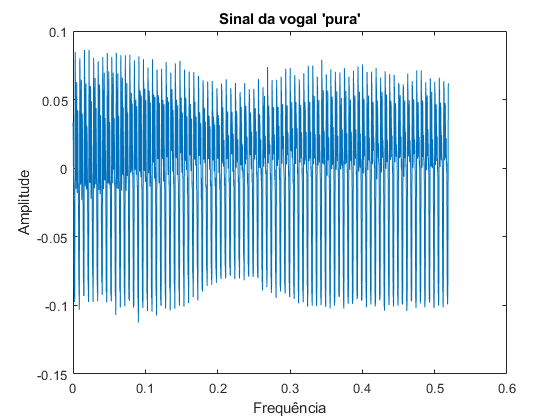

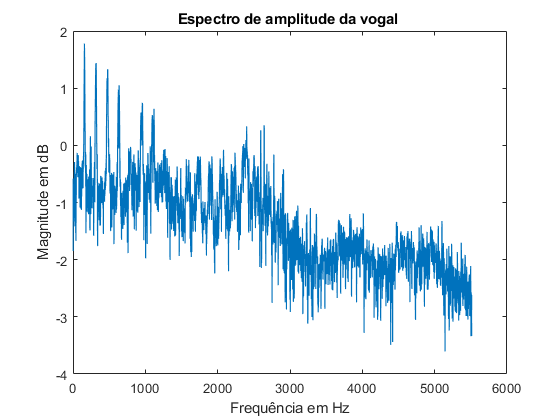

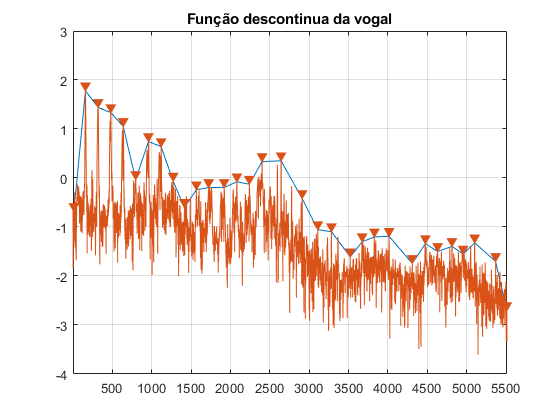

f0 = 158.9866

f1 = 958.7375

f2 = 1.4155e+03

fx =      General model Exp1:
     fx(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.08608  (-0.1844, 0.3565)
       b =      -513.8  (-2933, 1905)

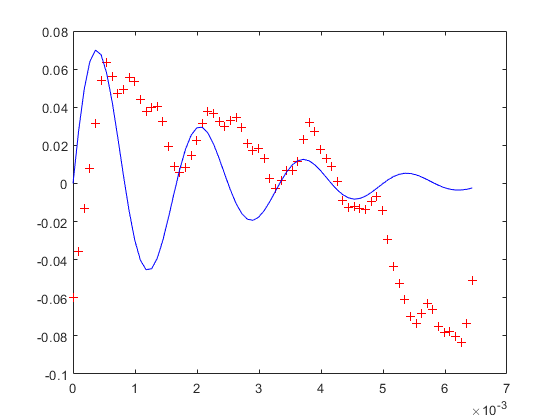

Gs =
 
           324.52
  ------------------------
  (s^2 + 1028s + 1.448e07)
 
Continuous-time zero/pole/gain model.



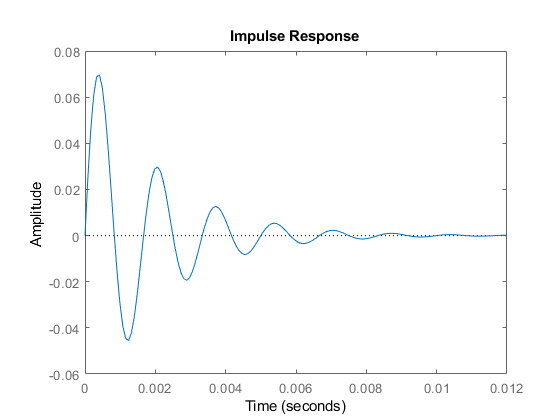

impulso_e = get_sintese(VG_e, fs_e, 600);

sound(impulso_e,fs_e*2)
pause(1)

%Vogal I
[VG_i, fs_i] = audioread("i1.wav");
disp("VOGAL I")

VOGAL I


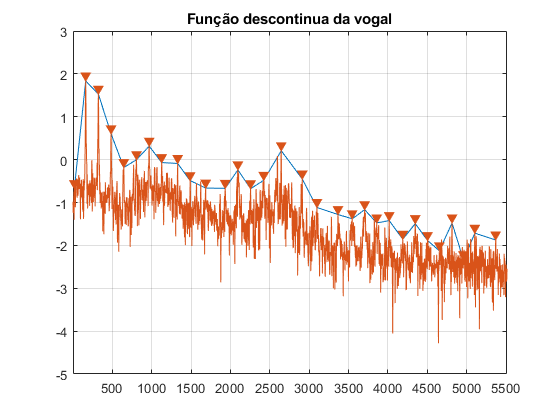

f0 = 162.6639

f1 = 969.0322

f2 = 1.9339e+03

fx =      General model Exp1:
     fx(x) = a*exp(b*x)
     Coefficients:
       a =      0.1807
       b =        -603

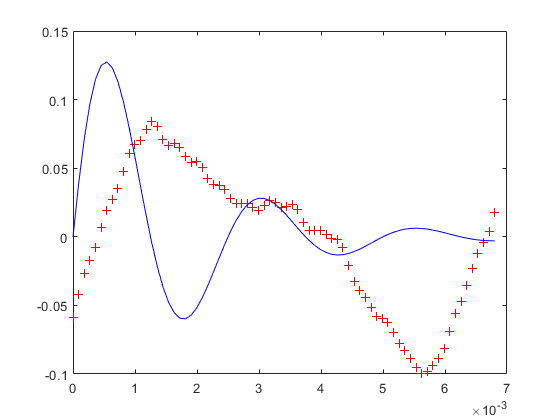

Gs =
 
          454.07
  -----------------------
  (s^2 + 1206s + 6.68e06)
 
Continuous-time zero/pole/gain model.



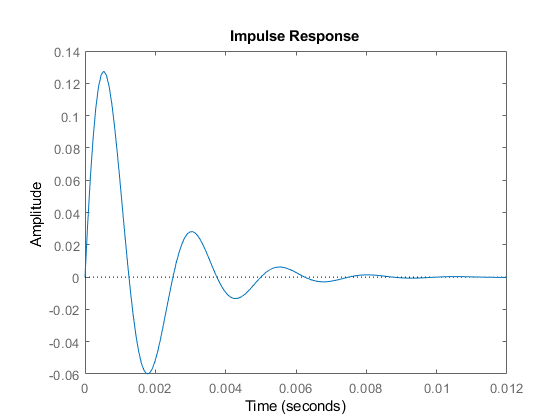

impulso_i = get_sintese(VG_i, fs_i, 400);

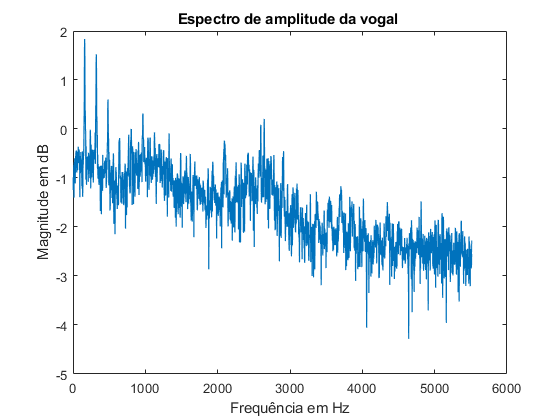

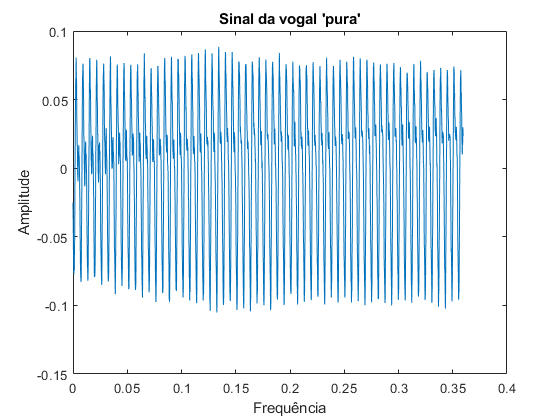

sound(impulso_i,fs_i*2)
pause(1)


%Vogal O
[VG_o, fs_o] = audioread("o1.wav");
disp("VOGAL O")

VOGAL O


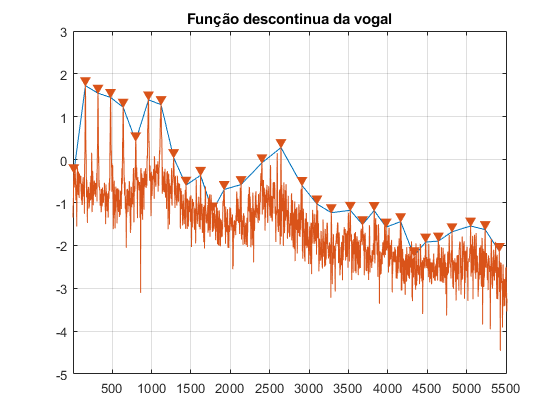

f0 = 159.7103

f1 = 960.7571

f2 = 1.4374e+03

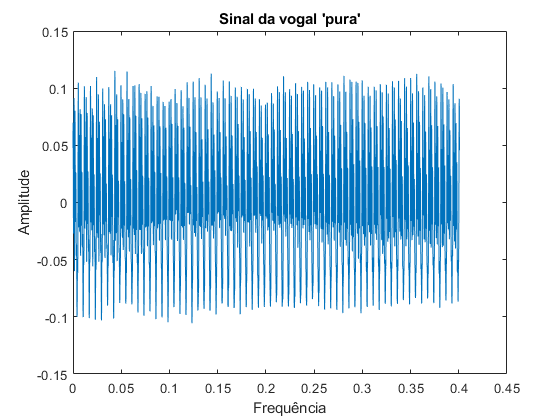

fx =      General model Exp1:
     fx(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1129  (-0.2, 0.4258)
       b =      -376.6  (-2229, 1476)

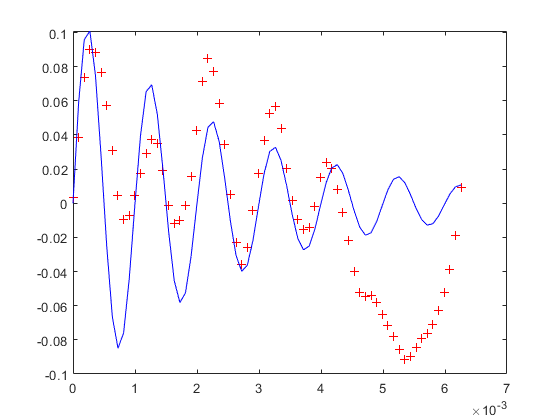

Gs =
 
           709.34
  -------------------------
  (s^2 + 753.2s + 3.962e07)
 
Continuous-time zero/pole/gain model.



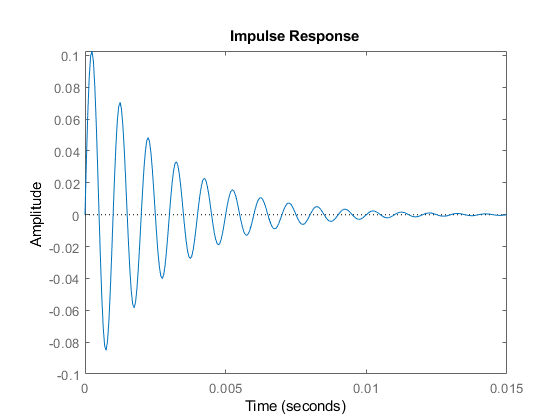

impulso_o = get_sintese(VG_o, fs_o, 1000);

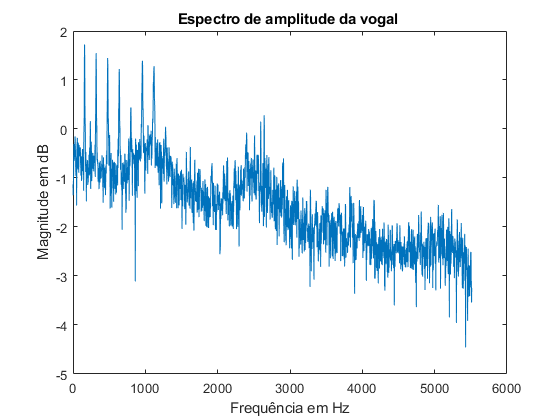

sound(impulso_o,fs_o*2)
pause(1)


%Vogal U
[VG_u, fs_u] = audioread("u1.wav");
disp("VOGAL U")

VOGAL U


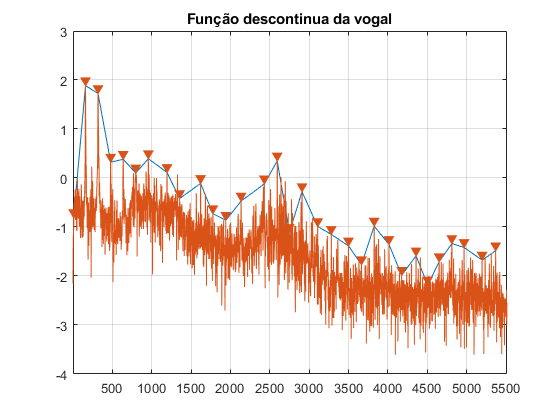

f0 = 160.5583

f1 = 638.9894

f2 = 958.4841

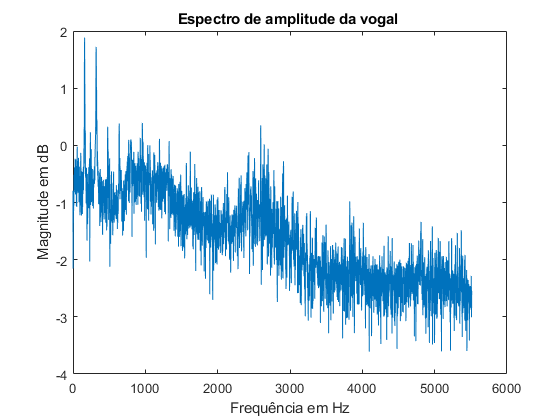

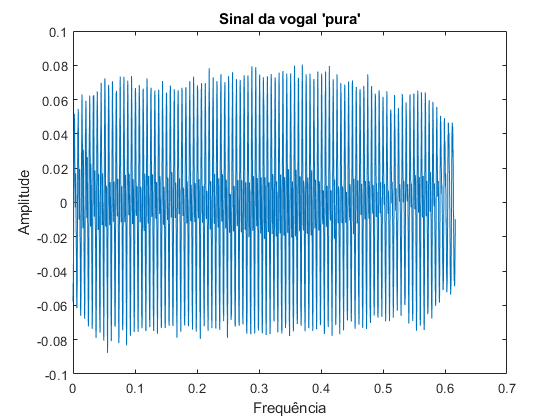

fx =      General model Exp1:
     fx(x) = a*exp(b*x)
     Coefficients:
       a =      0.1478
       b =      -812.5

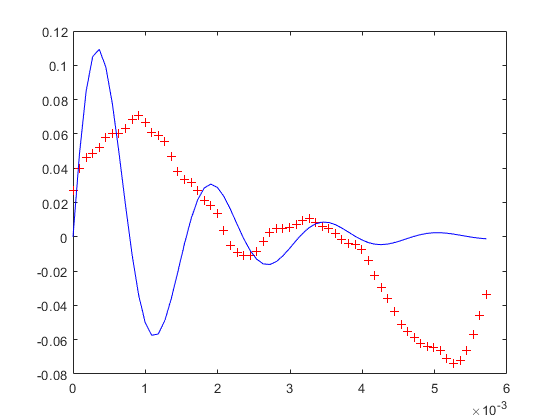

Gs =
 
           593.14
  ------------------------
  (s^2 + 1625s + 1.678e07)
 
Continuous-time zero/pole/gain model.



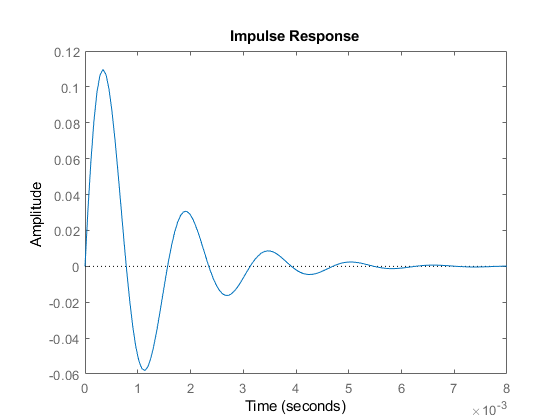

impulso_u = get_sintese(VG_u, fs_u, 638.9);

sound(impulso_u,fs_u*2)

## Sequência AUA

% A
sound(impulso_a,fs_a*2)
pause(1)

% U
sound(impulso_u,fs_u*2)
pause(1)

% A
sound(impulso_a,fs_a*2)